load sensorlog_20190714.mat Acceleration
Acceleration

Acceleration = 3659×3 timetable
           Timestamp               X         Y         Z   
    ________________________    _______    ______    ______

    14-Jul-2019 18:50:47.460    -2.3973    4.8675    8.5014
    14-Jul-2019 18:50:47.479    -2.4019    4.7424    9.3153
    14-Jul-2019 18:50:47.498    -1.8466    4.5503    8.7102
    14-Jul-2019 18:50:47.517    -1.6383    4.5592    8.2152
    14-Jul-2019 18:50:47.536    -1.6238    4.5992    8.3159
    14-Jul-2019 18:50:47.555    -1.9466    4.6871    8.0435
    14-Jul-2019 18:50:47.574    -1.9704    4.7821    7.9887
    14-Jul-2019 18:50:47.593    -1.5395     4.602    8.0393
    14-Jul-2019 18:50:47.612    -1.2953     4.453     8.511
    14-Jul

Acceleration= retime(Acceleration, "regular","linear","SampleRate" , 50)

Acceleration = 3478×3 timetable
           Timestamp               X         Y         Z   
    ________________________    _______    ______    ______

    14-Jul-2019 18:50:47.460    -2.3973    4.8675    8.5014
    14-Jul-2019 18:50:47.480    -2.3727    4.7323    9.2834
    14-Jul-2019 18:50:47.500    -1.8247    4.5513    8.6581
    14-Jul-2019 18:50:47.520     -1.636    4.5655    8.2311
    14-Jul-2019 18:50:47.540    -1.6917    4.6177    8.2586
    14-Jul-2019 18:50:47.560    -1.9529    4.7121    8.0291
    14-Jul-2019 18:50:47.580    -1.8343    4.7253    8.0047
    14-Jul-2019 18:50:47.600    -1.4495    4.5471     8.213
    14-Jul-2019 18:50:47.620    -1.2811    4.4144    8.6894
    14-Jul

height(Acceleration)

ans = 3478

jogSignal = detrend(Acceleration.Y(Acceleration.Timestamp > "14-Jul-2019 18:51:32"))

jogSignal =    -1.7021
   -1.8624
   -2.0644
   -2.3310
   -2.5720
   -2.7085
   -2.4883
   -2.0819
   -1.8950
   -1.9201


[spectrum,frequencies] = periodogram(jogSignal,[],[],50)

spectrum =     0.0000
    0.8410
    1.0068
    0.5451
    0.4597
    0.3760
    0.7829
    0.8523
    0.7777
    0.6927


frequencies =          0
    0.0244
    0.0488
    0.0732
    0.0977
    0.1221
    0.1465
    0.1709
    0.1953
    0.2197


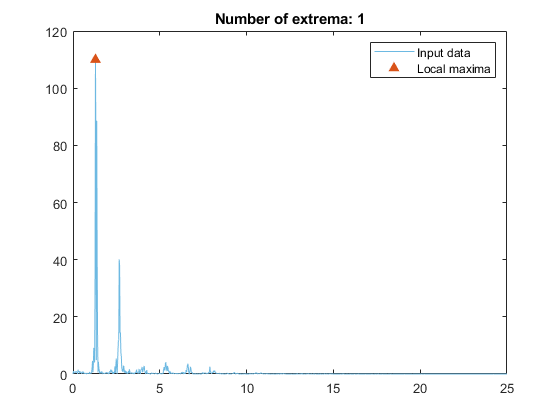

% Find local maxima
maxIndices2 = islocalmax(spectrum,'MaxNumExtrema',1,'SamplePoints',frequencies);

% Display results
clf
plot(frequencies,spectrum,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on

% Plot local maxima
plot(frequencies(maxIndices2),spectrum(maxIndices2),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxIndices2))])
hold off
legend

maxIndices2

maxIndices2 = 1025×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


spectrum(54,:)

ans = 109.9689

frequencies(54,:)

ans = 1.2939

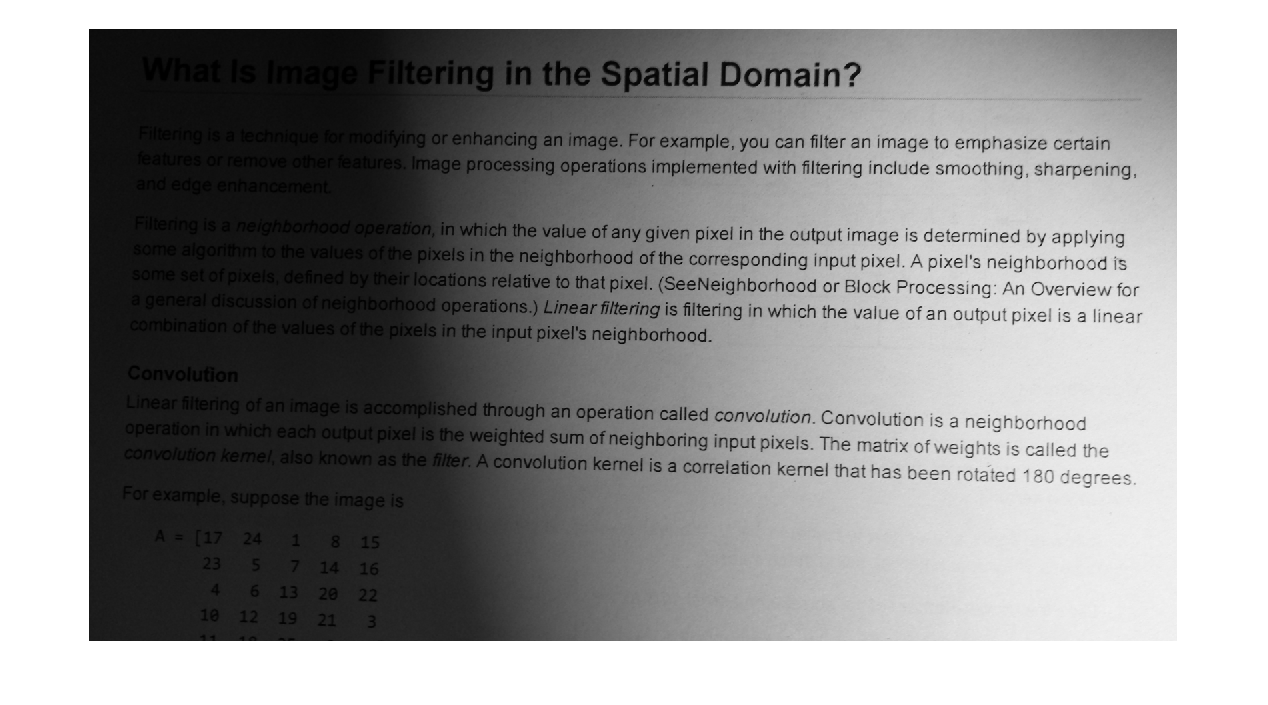

textImage = imread("printedtext.png");
imshow(textImage)

BW = segmentImage(textImage);
ocrOutput = ocr(BW);
ocrText = string(ocrOutput.Text)

ocrText =     " 
     
     What is Image Filtering in the Spatial Domain?
     
     Filtering is a technique formodliying or enhancing an image. For example, you can ﬁlter an Image to emphasize certain
     features or remove other feamres. Image processing operations implemented with ﬁltering include smoothing, sharpening,
     
     and edge enhancement
     Filtering is a neighborhoodoparaﬁon, in which the value ofany given pixel in the output image is determined by applying
     some algorithm to the values oflhe pixels in the neighborhood of the corresponding input pixel. A pixe|'s neighborhood is
     
     some set ofpixels. deﬁned by their locations relative to that pixel‘ (SeeNeighborhood or Block Processing: An Overview for
     a general discussion of neighborhood operations.) L/near ﬁltering is ﬁltering in which the value ofan output pixel is a linear
     
     combination of the values of the pixels in the input pixel‘s neighborhood.
     
     Convolution
     /ut/‘on.

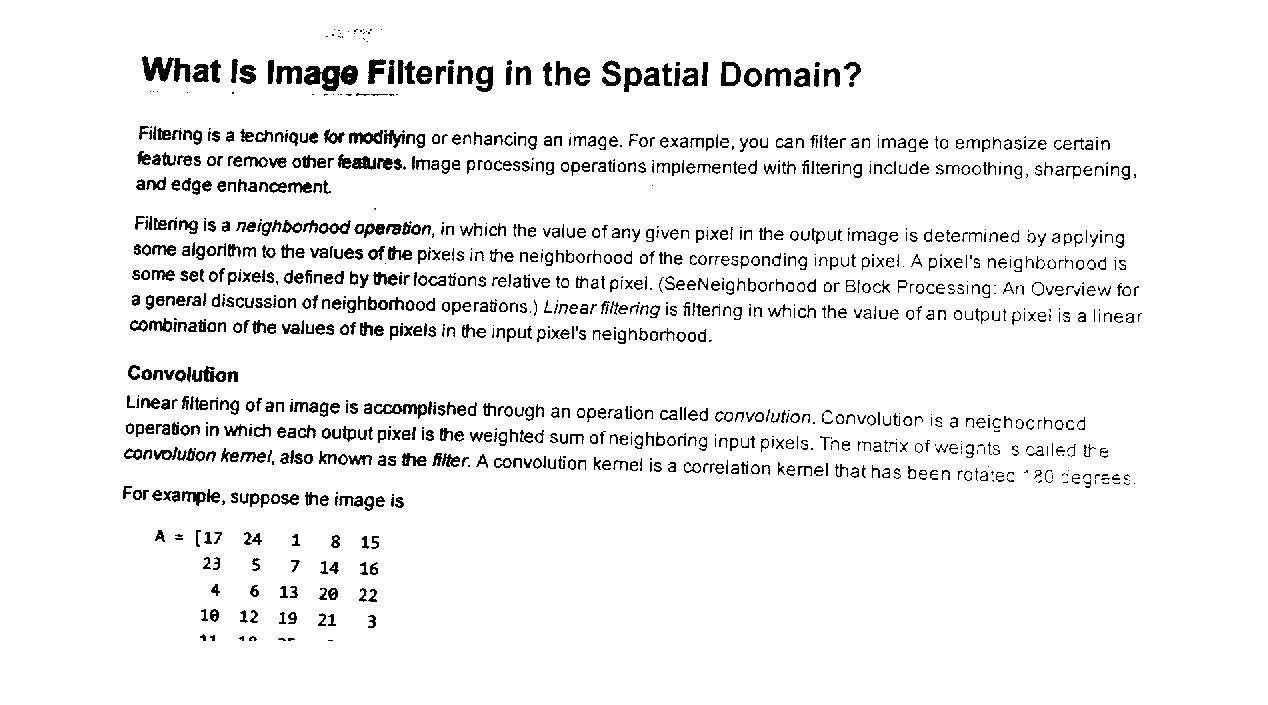

imshow(BW)

tokenizedtexts = tokenizedDocument(ocrText)

tokenizedtexts =   tokenizedDocument:

   220 tokens: What is Image Filtering in the Spatial Domain ? Filtering is a technique formodliying or enhancing an image . For example , you can ﬁlter an Image to emphasize certain features or remove other feamres . Image processing operations implemented with ﬁltering include smoothing , sharpening , and edge enhancement Filtering is a neighborhoodoparaﬁon , in which the value ofany given pixel in the output image is determined by applying some algorithm to the values oflhe pixels in the neighborhood of the corresponding input pixel . A pixe | ' s neighborhood is some set ofpixels . deﬁned by their locations relative to that pixel ‘ ( SeeNeighborhood or Block Processing : An Overview for a general discussion of neighborhood operations . ) L / near ﬁltering is ﬁltering in which the value ofan output pixel is a linear combination of the values of the pixels in the input pix

You can visualize the most common tokens ranked using appearance size with the [`wordcloud`](https://www.mathworks.com/help/matlab/ref/wordcloud.html) function. 

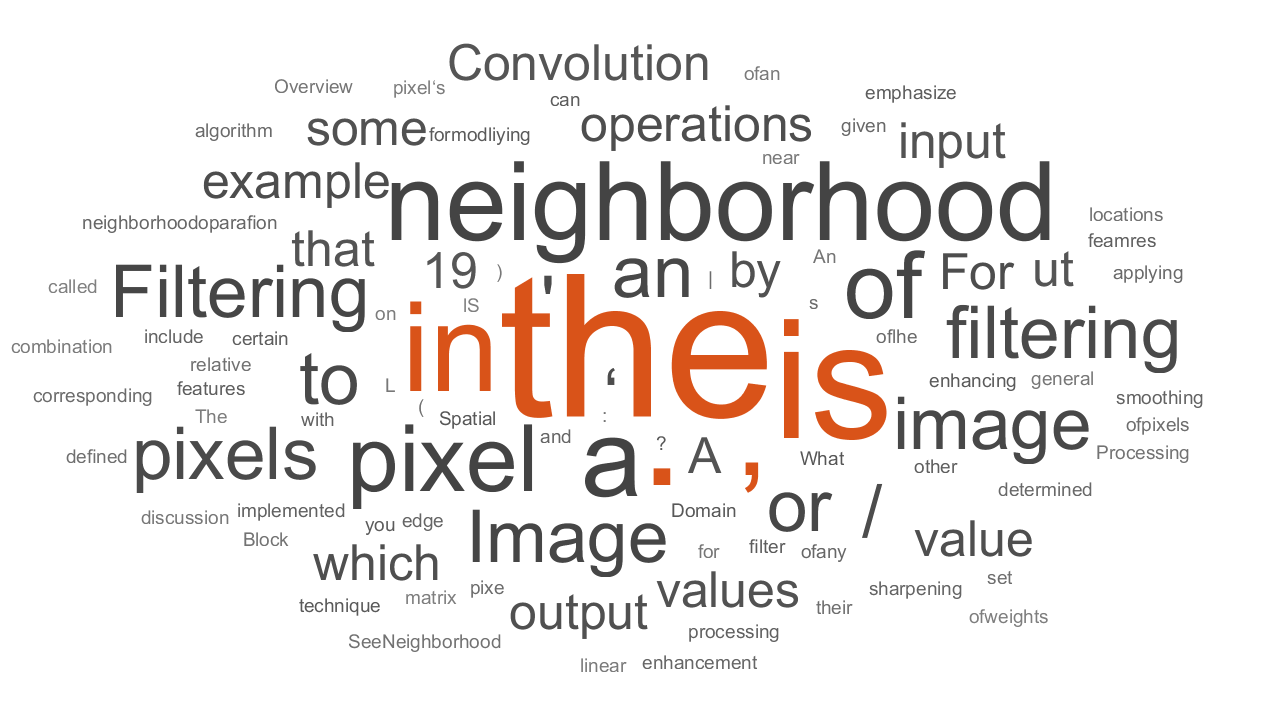

wordcloud(tokenizedtexts);

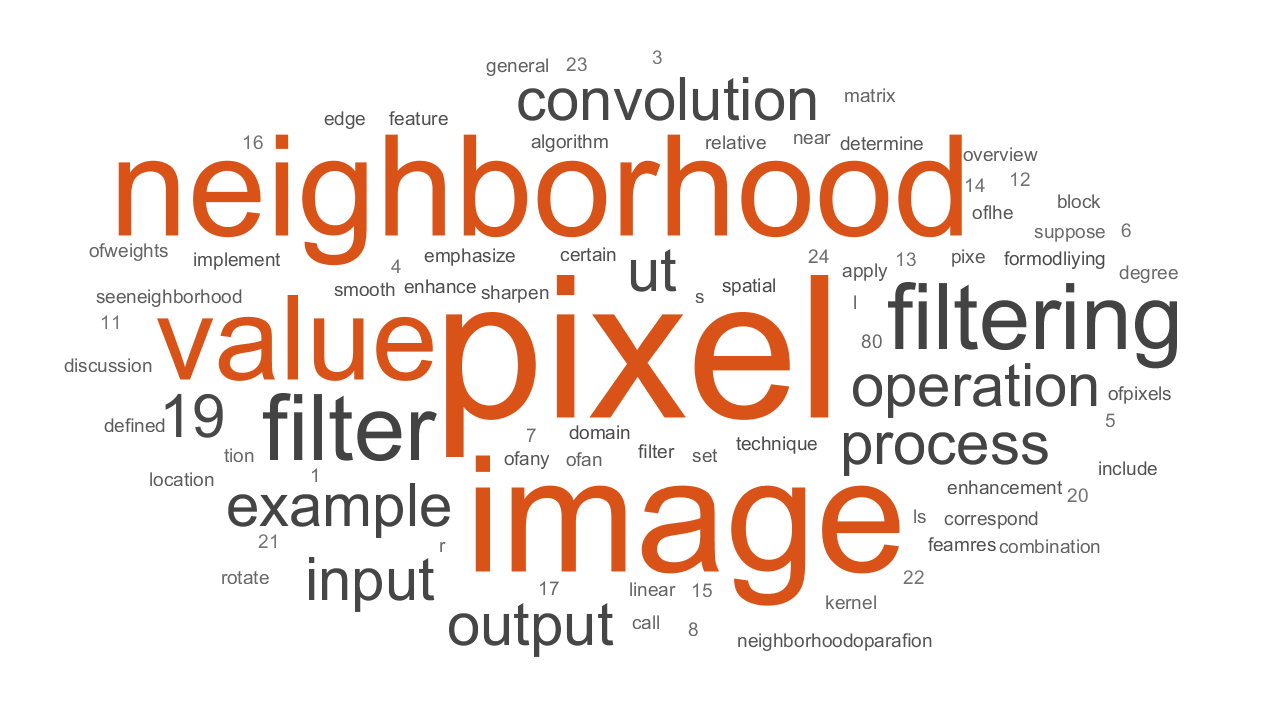

tokenizedtexts = erasePunctuation(tokenizedtexts); 
tokenizedtexts = removeStopWords(tokenizedtexts); 
tokenizedtexts = lower(tokenizedtexts); 
tokenizedtexts = normalizeWords(tokenizedtexts,"Style","Lemma");
wordcloud(tokenizedtexts);